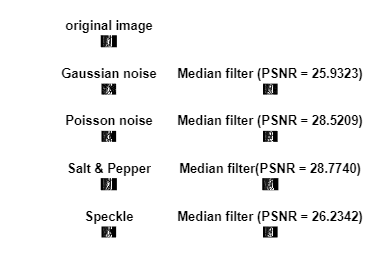

clc;
clear all;
close all;
im = imread("spine.jpg");
im1 = rgb2gray(im);

%adding noise
gau = imnoise(im1,"gaussian");
pois = imnoise(im1,"poisson");
sp = imnoise(im1,"salt & pepper");
spec = imnoise(im1,"speckle");

%original image
subplot(521);
imshow(im1); title("original image");

%gaussian
subplot(523);
imshow(gau);title("Gaussian noise");
subplot(524);
a = uint8(medfilter(gau));
imshow(a);title(sprintf("Median filter (PSNR = %3.4f)",psnr(a,im1)));

%poisson
subplot(525);
imshow(pois);title("Poisson noise");
subplot(526);
b = uint8(medfilter(pois));
imshow(b);title(sprintf("Median filter (PSNR = %3.4f)",psnr(b,im1)));

%salt & pepper
subplot(527);
imshow(sp);title("Salt & Pepper");
subplot(528);
c = uint8(medfilter(sp));
imshow(c);title(sprintf("Median filter(PSNR = %3.4f)",psnr(c,im1)));

%speckle
subplot(529);
imshow(spec);title("Speckle");
subplot(5,2,10);
d = uint8(medfilter(spec));
imshow(d);title(sprintf("Median filter (PSNR = %3.4f)",psnr(d,im1)));

function y = medfilter(a)
[r,c] = size(a);
y = zeros(r,c);
for i = 1:r-2
    for j = 1:c-2
       y(i,j) = median(a(i:i+2,j:j+2),"all");
    end
end
end